# MLER example

Extreme conditions modeling consists of identifying the expected extreme (e.g. 100-year) response of some quantity of interest, such as WEC motions or mooring loads. Three different methods of estimating extreme conditions were adapted from [WDRT](https://github.com/WEC-Sim/WDRT): full sea state approach, contour approach, and MLER design wave. This noteboook presents the MLER approach.

This example notebook shows users how to utilze the most likely extreme response (MLER) method. This method is an alternative to exhaustive Monte Carlo or long-term simulations for finding and evaluating wave energy converter response events at extreme loads. To accomplish this, a given RAO is combined with a wave spectrum corresponding to certain extreme sea states. MLER then generates the resulting wave profile that would cause the largest response for that degree of freedom. See full explanation and derivation of the MLER method in

*E. Quon, A. Platt, Y.-H. Yu, and M. Lawson, “Application of the Most Likely Extreme Response Method for Wave Energy Converters,” in Volume 6: Ocean Space Utilization; Ocean Renewable Energy, Busan, South Korea, Jun. 2016, p. V006T09A022. doi: 10.1115/OMAE2016-54751.*

In this example, a simple ellipsoid shaped WEC device was modeled in WEC-Sim. We will focus on anayzing the heave response of this device. The code below simply imports RAO data as it is needed for one of the inputs.

wave_freq = linspace( 0,1,500);
mfile = readtable('data/loads/mler.csv');
RAO = mfile.RAO

RAO =    1.0000 + 0.0000i
   1.0000 - 0.0002i
   1.0000 - 0.0004i
   1.0000 - 0.0005i
   1.0000 - 0.0006i
   1.0001 - 0.0006i
   1.0001 - 0.0007i
   1.0001 - 0.0007i
   1.0001 - 0.0008i
   1.0001 - 0.0009i


Next, we need to generate a wave environment that corresponds to a chosen extreme sea state. The associated parameters are selected in different ways. In this case, public wave data was used to come up with estimated 100-year sea state contour. The sea state parameters were selected somewhere along the contour.

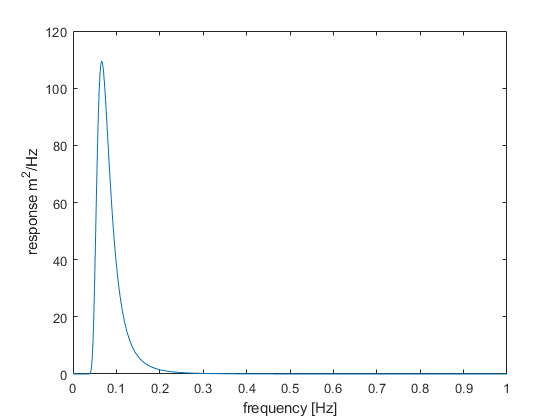

Hs = 9.0; % significant wave height
Tp = 15.1; % time period of waves
js = jonswap_spectrum(wave_freq, Tp, Hs);
plot(js.frequency, js.spectrum); xlabel('frequency [Hz]'); ylabel('response m^2/Hz')

Now that we have both the RAO and the spectrum of the wave environment, we can calculate the MLER conditioned wave spectrum and phase. In this case, we would like to find the wave profile that will generate a heave response of 1 meter for our WEC device.

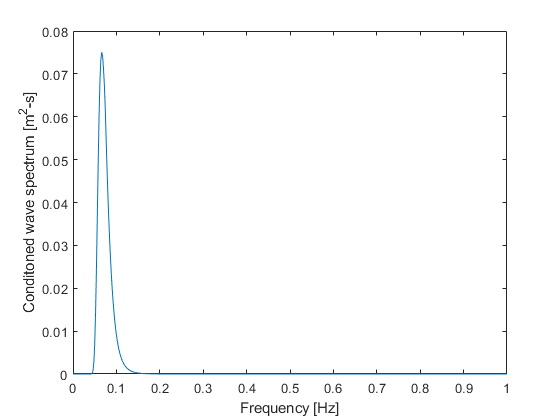

mler_data = mler_coefficients(RAO, js, 1);
plot(mler_data.frequency, mler_data.conditioned_spectrum); xlabel('Frequency [Hz]'); ylabel('Conditoned wave spectrum [m^2-s]')

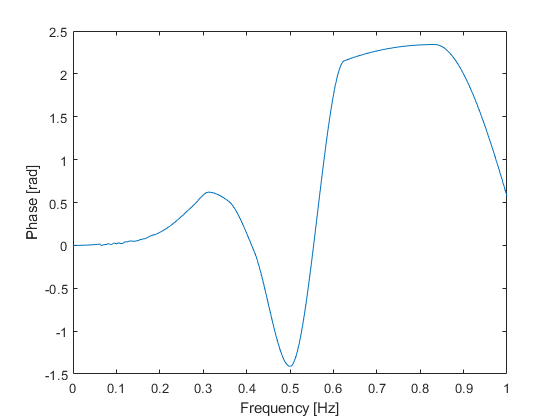

plot(mler_data.frequency, mler_data.phase); xlabel('Frequency [Hz]'); ylabel('Phase [rad]')

From here, we can choose to export these coefficients to feed into other high fidelity software. However, if we wanted to get a specific height of the incoming wave, we can renormalize the wave amplitude. To do this, several inputs need to be generated in addition to the existing coefficients.

The first is a struct containing information pertinent to creating time series. This struct can be easily generated using `mler_simulation`. In this example, the input dictionary contains the default values of this function, but the format is shown in case a user wants to adjust the parameters for their specific use case. The second input is the wave number, which was obtained using the `wave_number` function from the resource module. Finally, we decide to renormalize the wave amplitude to a desired peak height (peak to MSL). Combining all of these inputs into `mler_wave_amp_normalize` gives us our new normalized mler wave spectrum.

sim.startTime = -150.0;  % .s Starting time
sim.endTime = 150.0;  % .s Ending time
sim.dT = 1.0;  % .s Time-step size
sim.T0 = 0.0;  % .s Time of maximum event

sim.startX = -300.0;  % .m Start of simulation space
sim.endX = 300.0;  % .m End of simulation space
sim.dX = 1.0;  % .m Horiontal spacing
sim.X0 = 0.0;  % .m Position of maximum event

sim = mler_simulation(sim)

sim = struct with fields:
    startTime: -150
      endTime: 150
           dT: 1
           T0: 0
       startX: -300
         endX: 300
           dX: 1
           X0: 0
        maxIT: 301
            T: [1×301 double]
        maxIX: 601
            X: [1×601 double]


k = wave_number(wave_freq, 70);
k.values = fillmissing(k.values,'constant',0);

peakHeightDesired = Hs/2 * 1.9;
mler_norm = mler_wave_amp_normalize(peakHeightDesired, mler_data, sim, k.values);

As a final step, a user might need to convert the MLER coefficients into a time series for input into higher fidelity software. We can do this by using the `mler_export_time_series` function. The result is a struct containing the wave height [m] and the linear response [*] indexed by time.

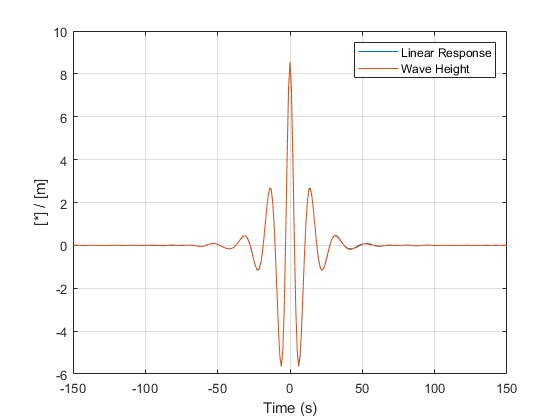

mler_ts = mler_export_time_series(RAO, mler_norm, sim, k.values);
plot(mler_ts.time, mler_ts.linear_response, mler_ts.time, mler_ts.wave_height); 
xlabel('Time (s)'); ylabel('[*] / [m]'); grid on; legend('Linear Response', 'Wave Height')